clear all
close all 
mask_struct = open("image_data_mask.mat");
image_struct = open("image_data.mat");


mask_img = mask_struct.out.image_data_masked;
whole_img =  mask_struct.out.image_data;

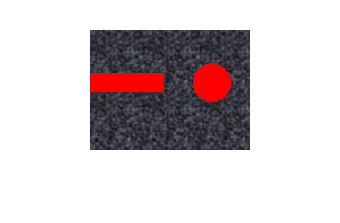

figure(1);
for i = 1:101
    imshow(whole_img(:,:,:,i));  % Added the closing parenthesis
    pause(0.2);  % Pauses for 0.2 seconds before showing the next frame
end

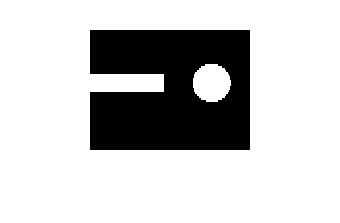

figure(2)
for i = 1:101
    imshow(mask_img(:,:,i));  % Added the closing parenthesis
    pause(0.2);  % Pauses for 0.2 seconds before showing the next frame
end

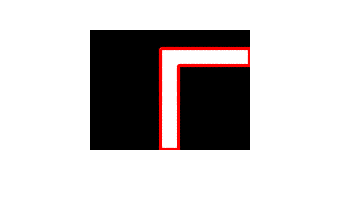

% Assuming BW is your binary mask showing the red line
% Use bwboundaries to find the contours of the white regions
BW = mask_img(:,:,30);
boundaries = bwboundaries(BW);

% Visualize the original image with contours
imshow(BW);
hold on;

% Loop through each boundary and plot it
for k = 1:length(boundaries)
    boundary = boundaries{k};
    plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);  % plot y, x coordinates
end
hold off;

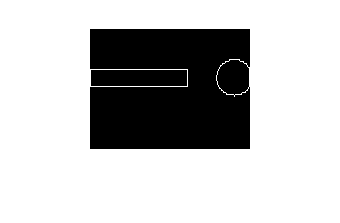

% Assuming BW is your binary mask showing the red line
% Use bwboundaries to find the contours of the white regions
figure(2)
for i = 1:101
    BW = mask_img(:,:,i);
    boundaries = bwboundaries(BW);
    
    % Create a black image of the same size as the original image
    black_image = zeros(size(BW), 'like', BW);
    
    % Loop through each boundary and plot it in white
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        % Draw the boundary on the black image in white
        for i = 1:size(boundary, 1)
            black_image(boundary(i,1), boundary(i,2)) = 255;  % Set boundary pixels to white
        end
    end
    
    % Display the black image with white boundaries
    imshow(black_image);
    pause(0.2)
end